# Object Detection

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the previously trained network and the test images.

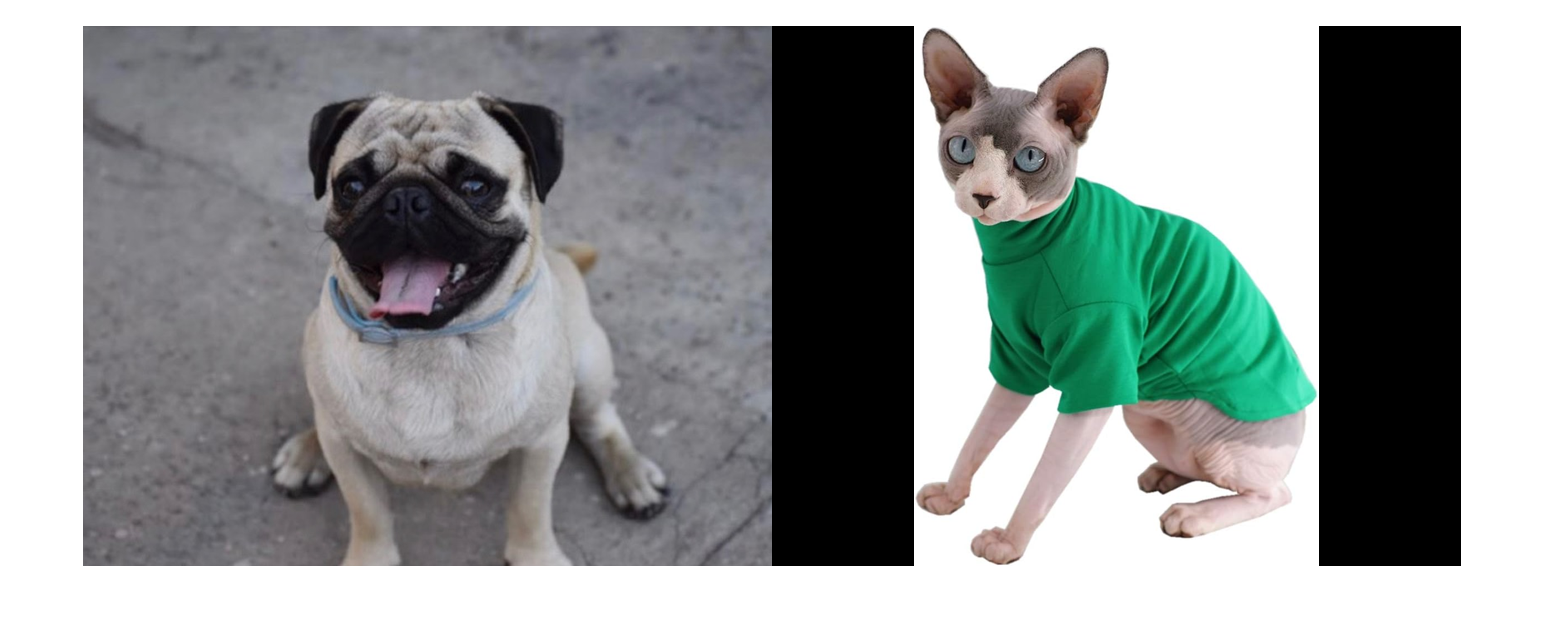

pathToImages = {'../data/PetsImages/TestImages/Pug.jpg'; '../data/PetsImages/TestImages/Sphinx.jpg'};
testImds = imageDatastore(pathToImages);
montage(testImds)

## Task 1

pugIm = readimage(testImds, 1);

This code trains and uses `detector` to detect pet faces in pugIm.

detector = trainNetwork();

*************************************************************************
Training a YOLO v2 Object Detector for the following object classes:

* Bengal
* Chihuahua
* Pug
* Samoyed
* Sphynx

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |         3.84 |         14.8 |          0.0010 |
|       4 |          50 |       00:00:25 |         0.61 |          0.4 |          0.0010 |
|       7 |         100 |       00:00:48 |         0.40 |          0.2 |          0.0010 |
|      10 |         150 |       00:01:13 |         0.27 |      7.2e-02 |          0.0010 |
|      14 |       

[pugBox, pugScore, pugLabel] = detect(detector, pugIm)

pugBox =    231    73   346   264


pugScore = single
0.7608

pugLabel = categorical
     Pug 


## Task 2

The output label from `detect` is a categorical array. You can use this label with `insertObjectAnnotation` to annotate the image:

`insertObjectAnnotation``(``im``,``"rectangle"``,``...`

`bbox``,``labels``)`

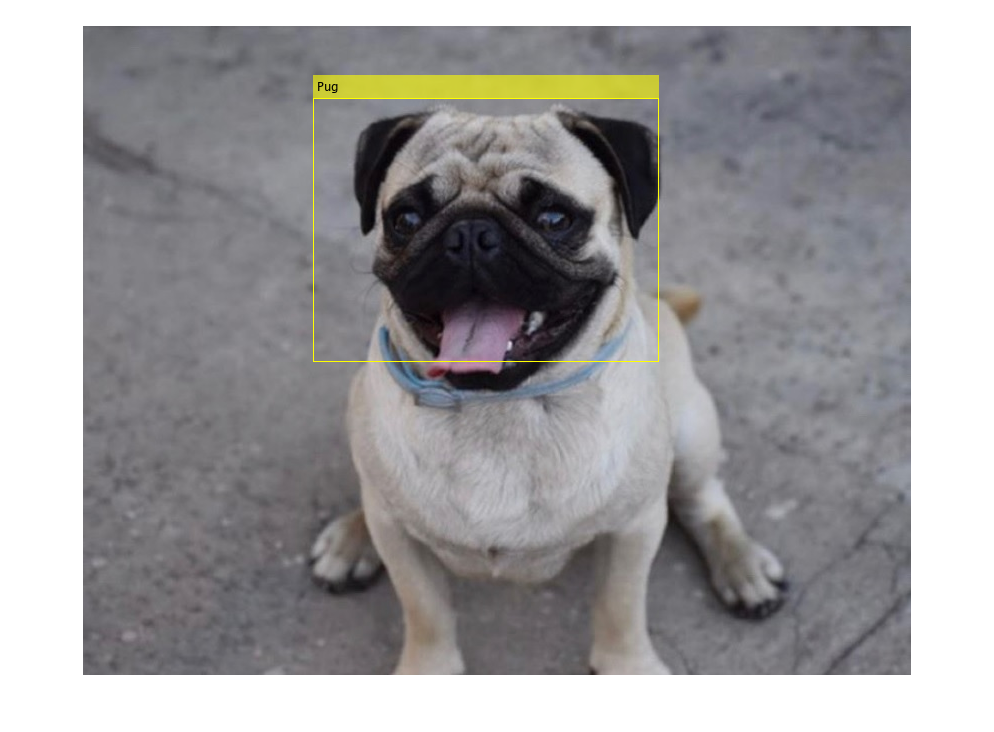

detectedPug = insertObjectAnnotation(pugIm, "rectangle", pugBox, pugLabel);
imshow(detectedPug)

## Task 3

The object detector found one Pug in this image. The next image is a Sphinx.

sphinxIm = readimage(testImds, 2);

This code uses `rcnn` to detect pet faces in sphinxIm.

[sphinxBox, sphinxScore, sphinxLabel] = detect(detector, sphinxIm)

sphinxBox =      1    31   349   357


sphinxScore = single
0.6580

sphinxLabel = categorical
     Sphynx 


## Task 4

The bounding boxes, scores, and labels were precomputed for the sphinxIm. The output variables are displayed.

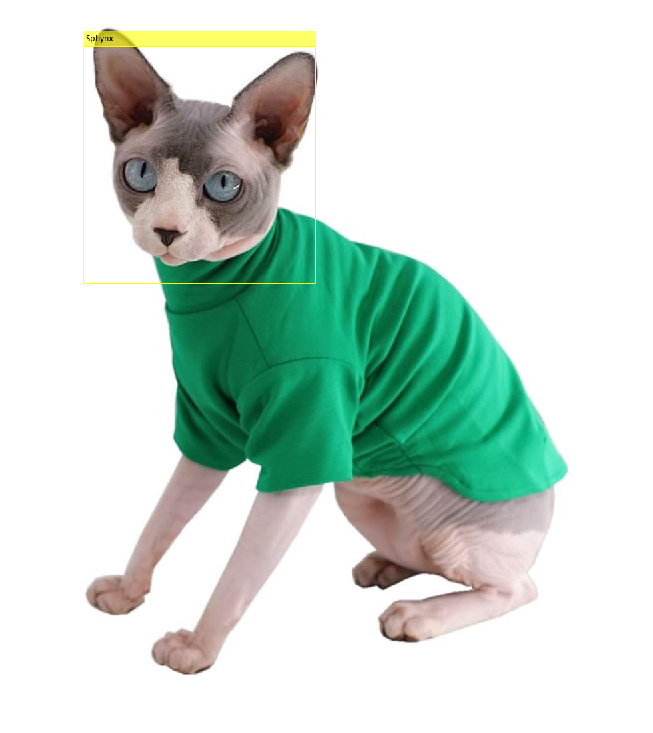

detectedSphinx = insertObjectAnnotation(sphinxIm, "rectangle", sphinxBox, sphinxLabel);
imshow(detectedSphinx)

function detector = trainNetwork()
    load ../data/PetsImages/petGroundTruth.mat petGroundTruth
    imds = imageDatastore(petGroundTruth.imageFilename);
    bxds = boxLabelDatastore(petGroundTruth(:, 2:end));
    data = combine(imds, bxds);
    scaledData = transform(data, @scaleGT);
    anchorBoxes = estimateAnchorBoxes(scaledData, 5);
    net = resnet18;
    numClasses = 5;
    imageSize = [224 224 3];
    lgraph = yolov2Layers(imageSize, numClasses, anchorBoxes, net,...
        "res5b_relu", "ReorgLayerSource", "res3a_relu");
    options = trainingOptions(  "adam", ...
                                "MiniBatchSize", 32, ...
                                "InitialLearnRate", 0.001, ...
                                "MaxEpochs", 15, ...
                                "Shuffle", "every-epoch", ...
                                "Verbose", true);
    detector = trainYOLOv2ObjectDetector(scaledData, lgraph, options);
end

function data = scaleGT(data)  
    targetSize = [224 224];
    % data{1} is the image
    scale = targetSize./size(data{1}, [1 2]);
    data{1} = imresize(data{1}, targetSize);
    % data{2} is the bounding box
    data{2} = bboxresize(data{2}, scale);
end